# Generation Of Seismic record as samples of a stationary process, characterized by a one-sided power spectral density (PSD) consistent with a given elastic pseudo-acceleration response spectrum.

Seismic codes allow ground motion representation by means of artificial accelerograms generated as parts of finite duration Ts of samples of a stationary process, characterized by a PSD consistent with the assigned elastic response spectrum.

In this script the following steps are implemented:

- The design pseudo-acceleration response spectrum of EC8 is calculated (EC8Sa)

- The one-sided Power Spectral Density (PSD) and Peak Factor (PF) of EC8Sa are calculated

- An artificial acceleration time history (ug) is generated based on the above PSD

- The pseudo-acceleration response spectrum of ug (PSa) is calculated and it is verified that PSa and EC8Sa are close to each other.

## Initial input

Duration of stationary seismic input (sec)

Ts=10;

Probability of outcrossing of peak value

p = 0.7;

Modal damping ratio

zeta=0.05;

Cut-off frequency (rad/s)

omegaC= 100;

Integration step (rad/s) and Lowest bound of the existence domain of etaXi (rad/s)

dOmega=0.1;
omega0=0.36;

done

## Normalized design pseudo-acceleration response spectrum of EC8

Circular frequency range

omega=(omega0+dOmega/2:dOmega:omegaC)';

Eigenperiod range for which the response spectrum will be calculated.

Tspectra=2*pi./omega;

Selection of spectrum parameters

q=3;
GroundType='A';
SeismicZone=1;
ImportanceFactor=1;

Calculation

[S,Tb,Tc,Td,ag,b]=paramEC8(GroundType,SeismicZone,ImportanceFactor);
EC8Sa = 2*specAccEC8(Tspectra,q,S,Tb,Tc,Td,ag,b);

## One sided PSD and Peak Factor

Calculation

[G,etaX] = StochProcPSD(EC8Sa,omega,Ts,p,zeta,omega0,dOmega);

Plot and compare with Figure 1(a) of Cacciola et al. (2004), PFWN, soil type A

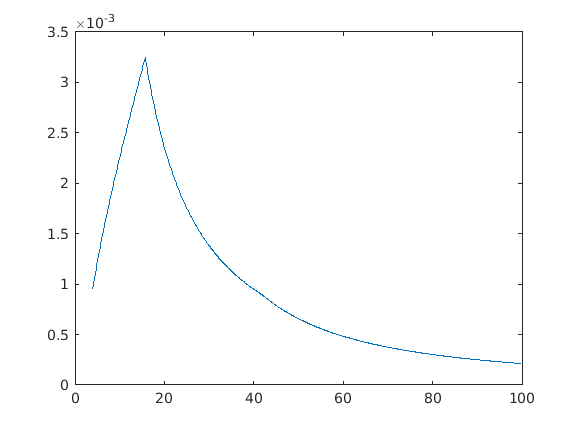

figure(1)
plot(omega(omega>4),G(omega>4))

## Artificial acceleration time history

Selection of time step

dt=0.02;

Calculation

[ug,t] = AccTHfromPSD(G,dt,Ts,dOmega);

Plot

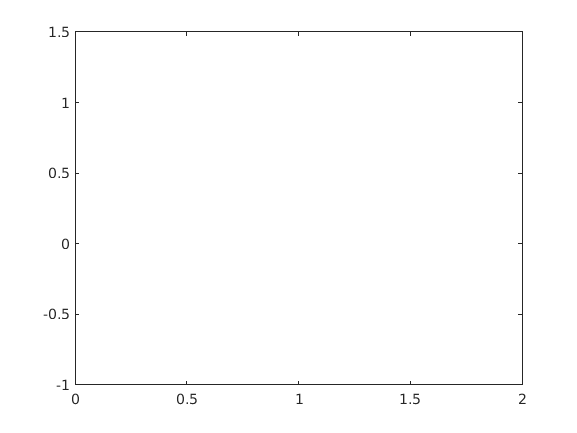

figure(2)
plot(t,ug)

function [ug,t] = AccTHfromPSD(G,dt,Ts,dOmega)
%
% Acceleration time history from a one sided Power Spectral Density (PSD)
%
% ug = AccTHfromPSD(G,dt,Ts,dOmega)
%
% Description
%     This function calculates an acceleration time history that
%     corresponds to the given one sided Power Spectral Density (PSD). See
%     the function StochProcPSD.m for the calculation of PSD. 
%     The methodology is used for the response spectrum based analysis of
%     nonlinear and non-classically damped systems in the following
%     reference:
%     Mitseas, I. P., & Beer, M. (2019). Modal decomposition method for
%     response spectrum based analysis of nonlinear and non-classically
%     damped systems. Mechanical Systems and Signal Processing, 131,
%     469-485.
%
% Input parameters
%     #G# ([#n# x 1]) is the one sided Power Spectral Density (PSD) that is
%         calculated from the function StochProcPSD.m.
%     #dt# (scalar) is a time step arbitrarily selected for the computation
%         of the acceleration time history.
%     #Ts# (scalar) is the duration of stationary seismic input.
%     #dOmega# (scalar) is the integration step in the circular frequency
%         domain.
%
% Output parameters
%     #ug# ([#m# x 1]) is an acceleration time history corresponding to the
%         given one sided Power Spectral Density (PSD).
%
%__________________________________________________________________________

n=numel(G);
t=size(n,1);
ug=zeros(t,1);
for i=1:n
    ug=ug+sqrt(2*G(i)*dOmega)*cos(i*dOmega*dt+2*pi*rand);
end
end

param

function [S,Tb,Tc,Td,ag,b]=paramEC8(GroundType,SeismicZone,ImportanceFactor)
%
% [#S#,#Tb#,#Tc#,#Td#,#ag#,#b#]=paramEC8(#GroundType#,#SeismicZone#,...
%     #ImportanceFactor#)
%     Calculation of the properties of the Type 1 design response spectrum
%     of EC8. The values are taken from Table 3.2 and Figure 3.2 of
%     EC8-1[3.2.2.2(2)P]
%
% Input parameters
%     #GroundType# (scalar string) is type of the ground type. Possible
%         values are: 'A', 'B', 'C', 'D', 'E'.
%     #SeismicZone# (scalar integer) is the seismic zone. Possible
%         values are: 1, 2, 3.
%     #ImportanceFactor# (scalar double) is the importance factor.
%
% Output parameters
%     #S# (scalar): soil factor
%     #Tb# (scalar): lower limit of the period of the constant spectral
%         acceleration branch 
%     #Tc# (scalar): upper linlit of the period of the constant spectral
%         acceleration branch 
%     #Td# (scalar): value defining the beginning of the constant
%         displacement response range of the spectrum
%     #ag# (scalar): design ground acceleration on type A ground
%     #b# (scalar): lower bound factor for the horizontal design spectrum
%
% Example:
%     q=3; % behavior factor
%     GroundType='A';
%     SeismicZone=1;
%     ImportanceFactor=1;
%     [S,Tb,Tc,Td,ag,b]=paramEC8(GroundType,SeismicZone,ImportanceFactor)
%
%__________________________________________________________________________
% Copyright (c) 2018
%     George Papazafeiropoulos
%     Captain, Infrastructure Engineer, Hellenic Air Force
%     Civil Engineer, M.Sc., Ph.D. candidate, NTUA
%     Email: gpapazafeiropoulos@yahoo.gr
% _________________________________________________________________________
% Calculate S,Tb,Tc,Td according to ground type
switch GroundType
    case 'A'
        S=1;
        Tb=0.15;
        Tc=0.4;
    case 'B'
        S=1.2;
        Tb=0.15;
        Tc=0.5;
    case 'C'
        S=1.15;
        Tb=0.2;
        Tc=0.6;
    case 'D'
        S=1.35;
        Tb=0.2;
        Tc=0.8;
    case 'E'
        S=1.4;
        Tb=0.15;
        Tc=0.5;
end
Td=2; % alternatively, according to national annex (Td=2.5)
% agRHor: reference peak ground acceleration on type A ground
switch SeismicZone
    case 1
        agR=0.16*9.81; % seismic zone I
    case 2
        agR=0.24*9.81; % seismic zone II
    case 3
        agR=0.32*9.81; % seismic zone III
end
% Importance class & Importance factor (given in EC8-1[4.2.5(4)]
ag=ImportanceFactor*agR; % EC8-1[3.2.1(3)]
b=0.2; % EC8-1[3.2.2.5(4)P-NOTE]
end

spec

function  SA = specAccEC8(T,q,S,Tb,Tc,Td,ag,b)
%
% #SA# = specAccEC8(#T#,#q#,#S#,#Tb#,#Tc#,#Td#,#ag#,#b#)
%     Calculation of PSA according to EC8-1[3.2.2.5(4)P]
%
% Input parameters
%     #T# ([#n# x 1]): period vector
%     #q# (scalar): behavior factor
%     #S# (scalar): soil factor
%     #Tb# (scalar): lower limit of the period of the constant spectral
%         acceleration branch 
%     #Tc# (scalar): upper linlit of the period of the constant spectral
%         acceleration branch 
%     #Td# (scalar): value defining the beginning of the constant
%         displacement response range of the spectrum
%     #ag# (scalar): design ground acceleration on type A ground
%     #b# (scalar): lower bound factor for the horizontal design spectrum
%
% Output parameters
%     #SA# ([#n# x 1]): spectral acceleration
%
% Example:
%     T=(0.04:0.04:4)'
%     q=3;
%     GroundType='A';
%     SeismicZone=1;
%     ImportanceFactor=1;
%     [S,Tb,Tc,Td,ag,b]=paramEC8(GroundType,SeismicZone,ImportanceFactor);
%     SA = specAccEC8(T,q,S,Tb,Tc,Td,ag,b);
%     plot(T,SA)
%
%__________________________________________________________________________
% Copyright (c) 2018
%     George Papazafeiropoulos
%     Captain, Infrastructure Engineer, Hellenic Air Force
%     Civil Engineer, M.Sc., Ph.D. candidate, NTUA
%     Email: gpapazafeiropoulos@yahoo.gr
% _________________________________________________________________________
T1= 0<=T & T<=Tb;
SA(T1)=ag.*S.*(2/3+T(T1)./Tb.*(2.5./q-2/3));
T2= Tb<=T & T<=Tc;
SA(T2)=ag.*S.*2.5./q;
T3= Tc<=T & T<=Td;
SA(T3)=max(ag.*S.*2.5./q.*Tc./T(T3),b.*ag);
T4= Td<=T;
SA(T4)=max(ag.*S.*2.5./q.*Tc.*Td./T(T4).^2,b.*ag);
SA=SA';
end
    

stoch

function [G,etaX] = StochProcPSD(PSa,omega,Ts,p,zeta,omega0,dOmega)
%
% One sided PSD and Peak Factor of a given pseudo-acceleration spectrum
%
% [G,etaX] = StochProcPSD(PSa,omega,Ts,p,zetai,omega0,dOmega)
%
% Description
%     This function calculates the one sided Power Spectral Density (PSD)
%     and Peak Factor (PF) of the stochastic response process Xi of an
%     elastic oscillator of frequency omega and damping ratio zeta. The PDF
%     and PF are consistent with a given pseudoacceleration spectrum PSa.
%     PSa can be any design spectrum, e.g. the design spectrum of EC8. The
%     methodology implemented is presented in the following paper:
%     Cacciola, P., Colajanni, P., & Muscolino, G. (2004). Combination of
%     modal responses consistent with seismic input representation. Journal
%     of Structural Engineering, 130(1), 47-55.
%     The methodology is also used for the response spectrum based
%     analysis of nonlinear and non-classically damped systems in the
%     following reference:
%     Mitseas, I. P., & Beer, M. (2019). Modal decomposition method for
%     response spectrum based analysis of nonlinear and non-classically
%     damped systems. Mechanical Systems and Signal Processing, 131,
%     469-485.
%
% Input parameters
%     #PSa# ([#n# x 1]) Linear elastic pseudo-acceleration response
%         spectrum
%     #omega# ([#n# x 1]) is the circular frequencies for the calculation
%         of the PSD and PF
%     #Ts# (scalar) is the duration of stationary seismic input.
%     #p# (scalar) is teh probability of outcrossing of the peak value.
%     #zeta# (scalar) is the modal damping ratio.
%     #omega0# (scalar) is the lowest circular frequency bound in order for
%         etaX to exist.
%     #dOmega# (scalar) is the integration step in the circular frequency
%         domain.
%
% Output parameters
%     #G# ([#n# x 1]) is the one sided Power Spectral Density (PSD).
%     #etaX# ([#n# x 1]) is the one sided Power Spectral Density (PSD).
%
%__________________________________________________________________________
% Copyright (c) 2019
%     George Papazafeiropoulos
%     Captain, Infrastructure Engineer, Hellenic Air Force
%     Civil Engineer, M.Sc., Ph.D. candidate, NTUA
%     Email: gpapazafeiropoulos@yahoo.gr
%__________________________________________________________________________
% Peak factor
n=numel(omega);
etaX=zeros(n,1);
for i=1:n
    % ith modal undamped natural circular frequency of structure
    omegai=omega(i);
    % mean zero crossing rate of response process Xi
    NXi=Ts/2/pi*omegai*(1/(-log(p)));
    % spread factor of response process Xi
    deltaXi=sqrt(1-1/(1-zeta^2)*(1-2/pi*atan(zeta/sqrt(1-zeta^2)))^2);
    % peak factor of Xi process
    etaX(i)=sqrt(2*log(2*NXi*(1-exp(-deltaXi^1.2*sqrt(pi*log(2*NXi))))));
end
% One-sided Power Spectral Density of ground acceleration
G=0;
for i=2:n
    if omega(i)<omega0
        G=[G;0];
    else
        G=[G;4*zeta/(omega(i)*pi-4*zeta*omega(i-1))*(PSa(i)^2/etaX(i)^2-...
            dOmega*sum(G))];
    end
end
end
